## Matlab Cheatsheet

### How to represent polynomials in Matlab?

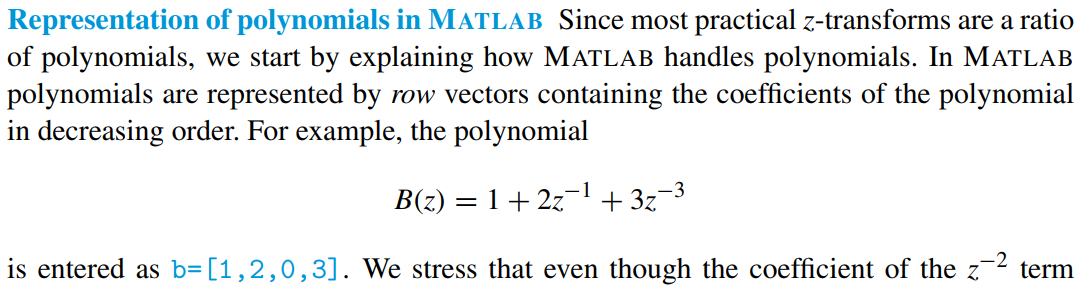

b = [1 2 0 3]

b =      1     2     0     3


### How to extract coefficients from polynomials?

Suppose we want to automatically get the coefficients of the following polynomial:


$$H\left(z\right)=-8+10z^{-1} -3z^{-2} -\frac{1}{2}z^{-3} +\frac{1}{4}z^{-4}$$


syms z;
H = -8 + 10*z^-1 - 3*z^-2 - 1/2*z^-3 + 1/4*z^-4;
H_b = coeffs(expand(H * z^4), 'all')

$$H\_b = \left(\begin{array}{ccccc} -8 & 10 & -3 & -\frac{1}{2} & \frac{1}{4} \end{array}\right)$$

B = 1 + 2*z^-1 + 3*z^-3;
B_b = coeffs(expand(B * z^3), 'all')

$$B\_b = \left(\begin{array}{cccc} 1 & 2 & 0 & 3 \end{array}\right)$$

### How to compute the roots of a polynomial?

b = [1 1.5 2];
z = roots(b)

z =   -0.7500 + 1.1990i
  -0.7500 - 1.1990i


### How to compute zero-pole representation of a transfer function?

Suppose we have the transfer function of a FIR filter:


$$H\left(z\right)=1+4\ldotp 5z^{-1} +2z^{-2}$$


Step 1: find the zeros:

zeros = roots([1, 4.5, 2])

zeros =    -4.0000
   -0.5000


We can see that there are two zeros at (-4, 0) and (-0.5, 0). Let us visualise it:

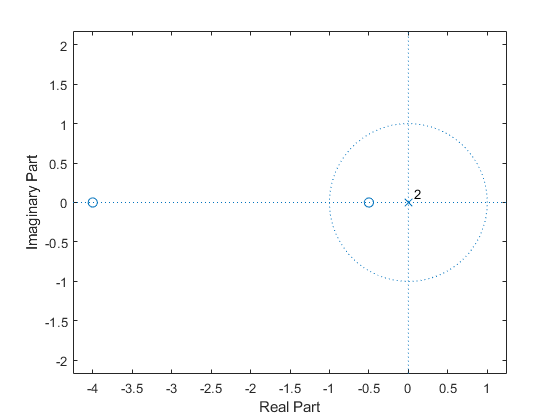

zplane([1, 4.5, 2]);

Step 2: use the formula $H\left(z\right)=b_0 \prod_k \left(1-z_k z^{-1} \right)$


$$H\left(z\right)=1\left(1+4z^{-1} \right)\left(1+0\ldotp 5z^{-1} \right)$$


### How to compute partial fraction expansion?

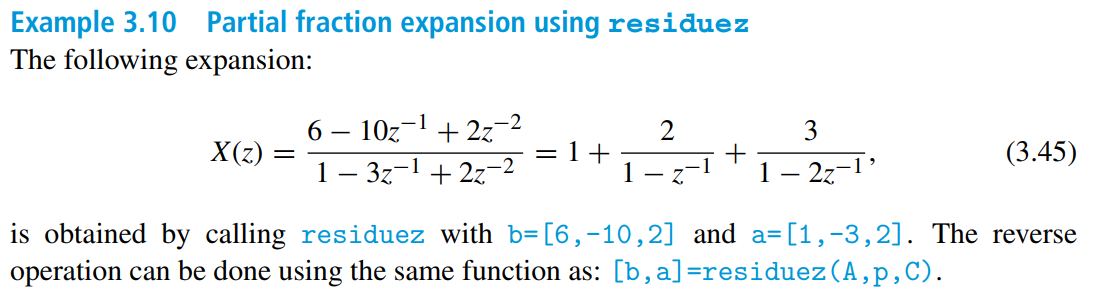

b = [ 6 -10  2];
a = [ 1  -3  2];

% Partial fraction expansion using residuez
[A,p,C] = residuez(b, a)

A =      3
     2


p =      2
     1


C = 1


% Reverse operation
[b, a] = residuez(A, p, C)

b =      6   -10     2


a =      1    -3     2


### How to perform polynomial multiplication?

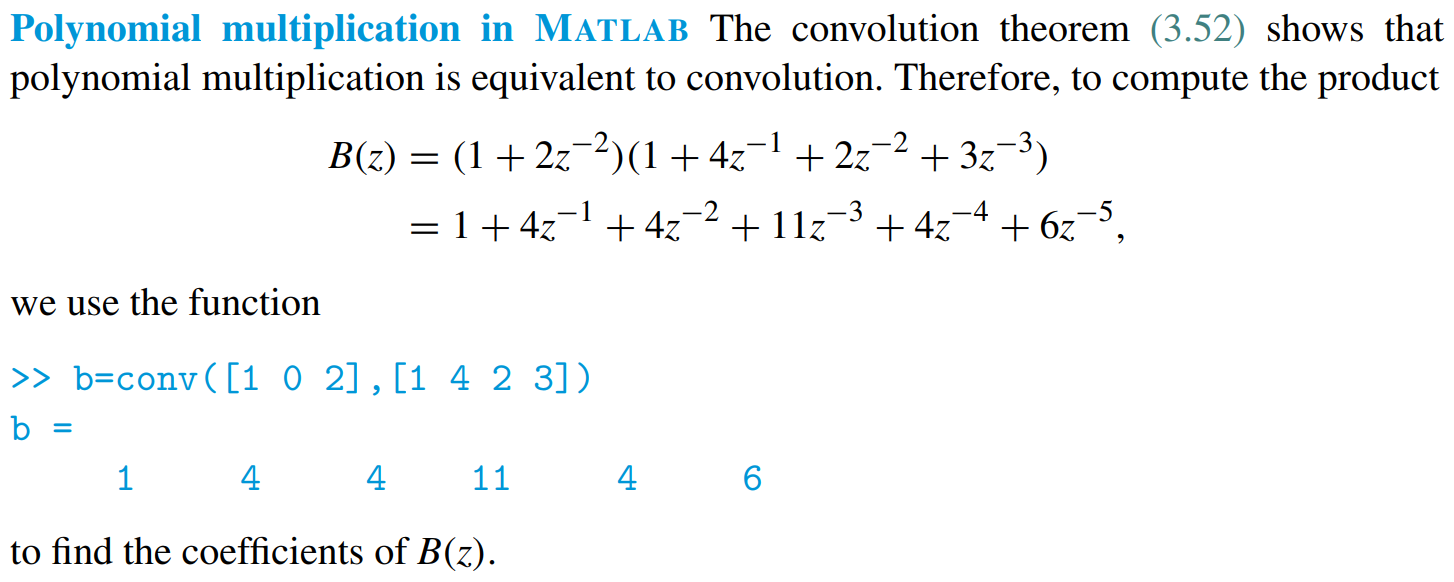

### How to convert a transfer function $H\left(z\right)$ to its frequency response $H\left(e^{j\omega } \right)$?

Suppose we have the following transfer function:


$$H\left(z\right)=\frac{0\ldotp 05634\left(1+z^{-1} \right)\left(1-1\ldotp 0166z^{-1} +z^{-2} \right)}{\left(1-0\ldotp 683z^{-1} \right)\left(1-1\ldotp 4461z^{-1} +0\ldotp 7957z^{-2} \right)}$$


We can express the numerator and denominator as polynomial convolutions:

b0 = 0.05634;
b1 = [1  1];
b2 = [1 -1.0166 1];
a1 = [1 -0.683];
a2 = [1 -1.4461 0.7957];

b = b0*conv(b1,b2);
a = conv(a1,a2);

We can use the freqz function to get the frequency response as a vector. The second output variable w is the angular frequencies.

[H,w] = freqz(b,a);

### How to plot the impulse reponse from a transfer function?

Suppose we have the following transfer function:

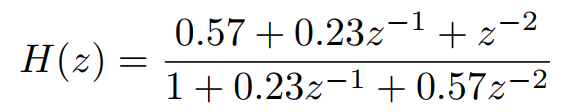

We can use the impz function:

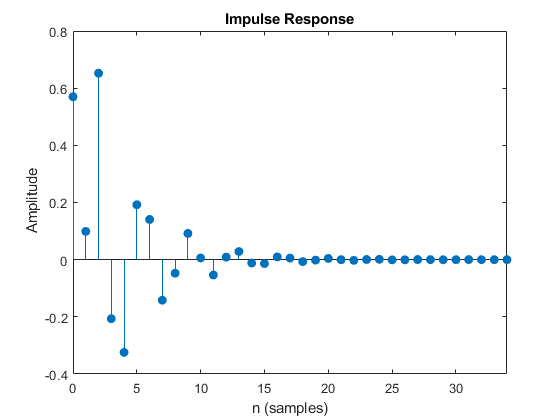

b = [0.57, 0.23, 1];
a = [1, 0.23, 0.57];
impz(b, a);

Alternatively, 

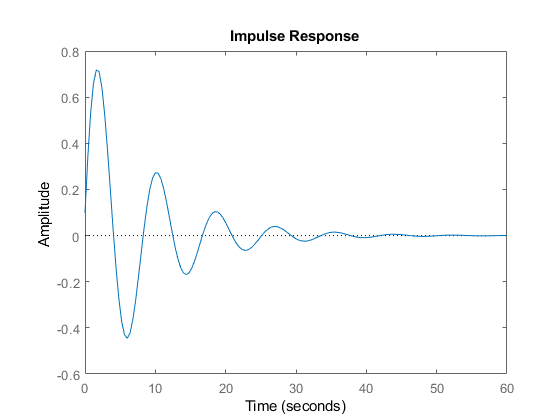

b = [0.57, 0.23, 1];
a = [1, 0.23, 0.57];
h = tf(b, a);
impulseplot(h);

### How to compute the group delay?

Suppose we have the following transfer function:

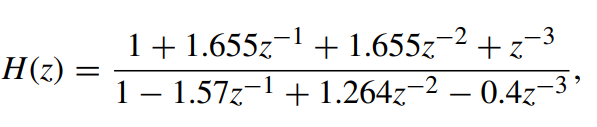

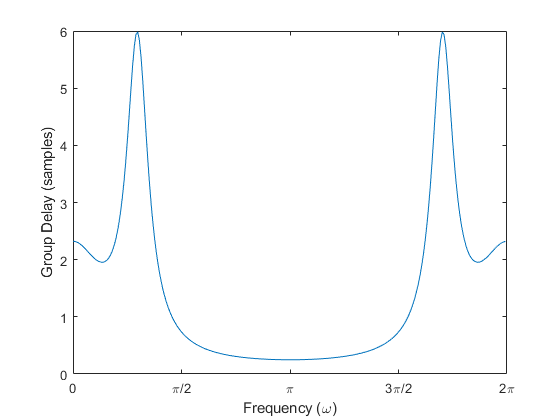

b = [1, 1.655, 1.655, 1];
a = [1, -1.57, 1.264, -0.4];
[gd, w] = grpdelay(b, a, 255, 'whole');

plot(w, gd);
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlabel('Frequency (\omega)')
ylabel('Group Delay (samples)')
xlim([0, 2*pi]);

### How to plot the zeros and poles?

Suppose we have the following transfer function:

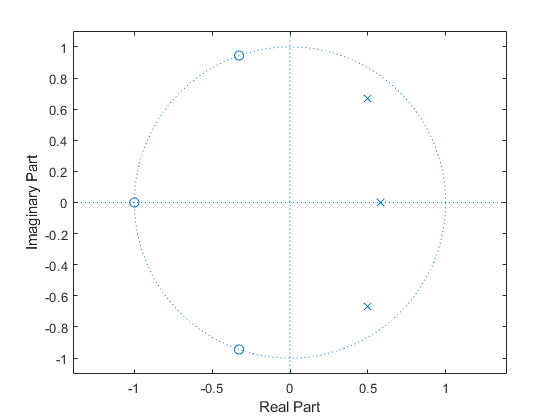

b = [1, 1.655, 1.655, 1];
a = [1, -1.57, 1.264, -0.4];
zplane(b, a);

### How to plot phase response (principle value) and continuos phase function?

Suppose we have the following transfer function:

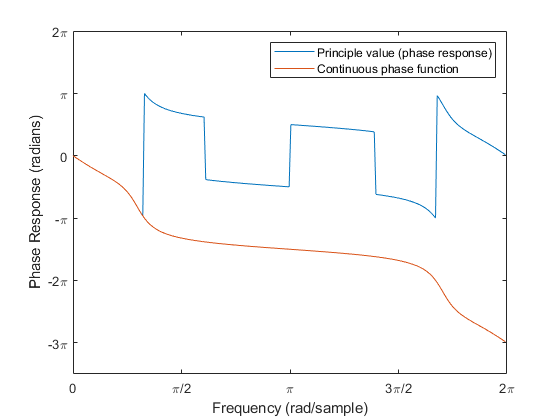

b = [1, 1.655, 1.655, 1];
a = [1, -1.57, 1.264, -0.4];

[gd, w] = grpdelay(b, a, 255, 'whole');
[H, w] = freqz(b, a, 255, 'whole');
plot(w, angle(H), w, contphase(gd, w));
legend('Principle value (phase response)','Continuous phase function')
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
set(gca,'YTick', -3*pi:pi:3*pi) 
set(gca,'YTickLabel',{'-3\pi', '-2\pi', '-\pi', '0','\pi','2\pi', '3\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Phase Response (radians)')
xlim([0, 2*pi]);
ylim([-3.5*pi, 2*pi]);

### How to plot the magnitude response?

Suppose we have the following transfer function:

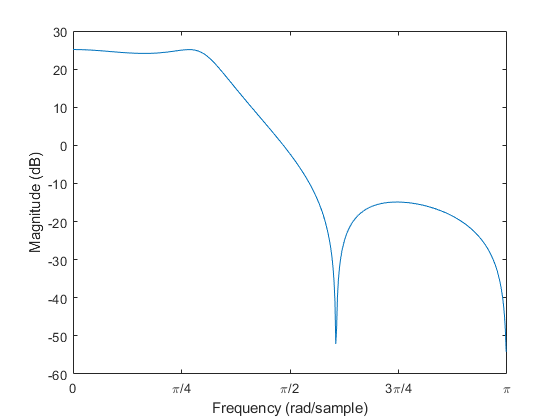

b = [1, 1.655, 1.655, 1];
a = [1, -1.57, 1.264, -0.4];
[H, w] = freqz(b, a);
plot(w, pow2db(H.*conj(H)));
set(gca,'XTick', 0:pi/4:pi)
set(gca,'XTickLabel', {'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude (dB)')
xlim([0, pi]);

### How to generate white Gaussian noise?

Use the function wgn.

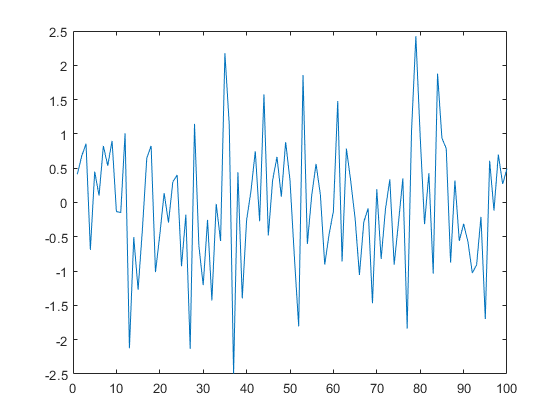

N = 100;
n = [1:N];
x = wgn(N,1,0);
plot(n, x)

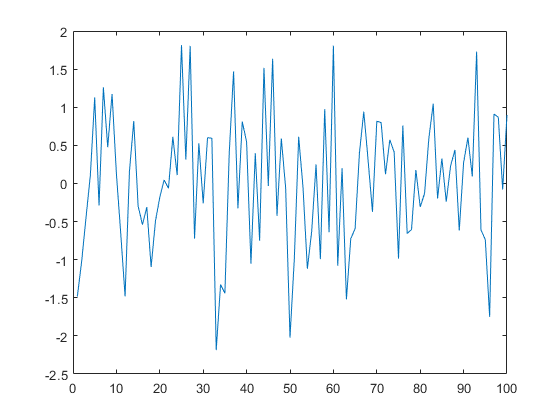

w = randn(N,1); 
plot(n, w)

### How to delay a signal?

Use the circshift function.

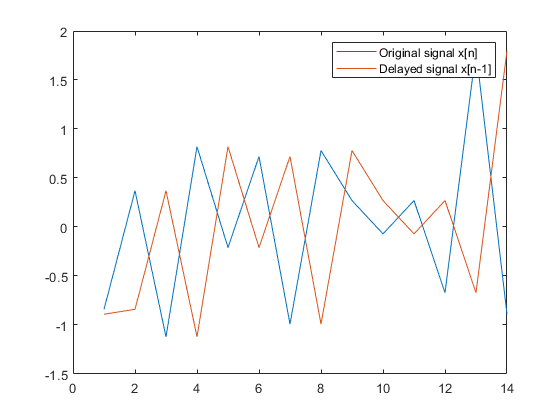

delay = 1;
x = [-0.84, 0.37, -1.12, 0.82, -0.21, 0.72, -0.99, 0.78, 0.27, -0.07, 0.27, -0.67, 1.80, -0.89];
N = numel(x);
n = [1:N];
plot(n, x, n, circshift(x, delay))
legend('Original signal x[n]', strcat('Delayed signal x[n-', num2str(delay), ']'))

### Functions

function cph=contphase(grd,om)
% Computation of continuous phase function
% from equidistant values of group delay
  N=length(om);
  dom=om(2)-om(1);
  p(1)=0;
  for k=2:N
    p(k)=p(k-1)+dom*(grd(k-1)+grd(k))/2;
  end
  cph=-p;
end